# 1.1.1

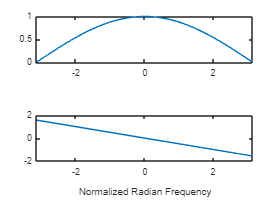

bb = [0.5, 0.5]; %-- Filter Coefficients
ww = -pi:(pi/100):pi; %-- omega hat
HH = freqz(bb, 1, ww); %<--freekz.m is an alternative
subplot(2,1,1);
plot(ww, abs(HH))
subplot(2,1,2);
plot(ww, angle(HH))
xlabel('Normalized Radian Frequency')

## 1.4

xx = 1.4:0.33:5

xx =     1.4000    1.7300    2.0600    2.3900    2.7200    3.0500    3.3800    3.7100    4.0400    4.3700    4.7000


jkl = find(round(xx)==3)

jkl =      5     6     7


xx(jkl)

ans =     2.7200    3.0500    3.3800



ww = -pi:(pi/500):pi; 
HH = freqz( 1/4*ones(1,4), 1, ww );

## 2.1 LTI Frequency Response Demo

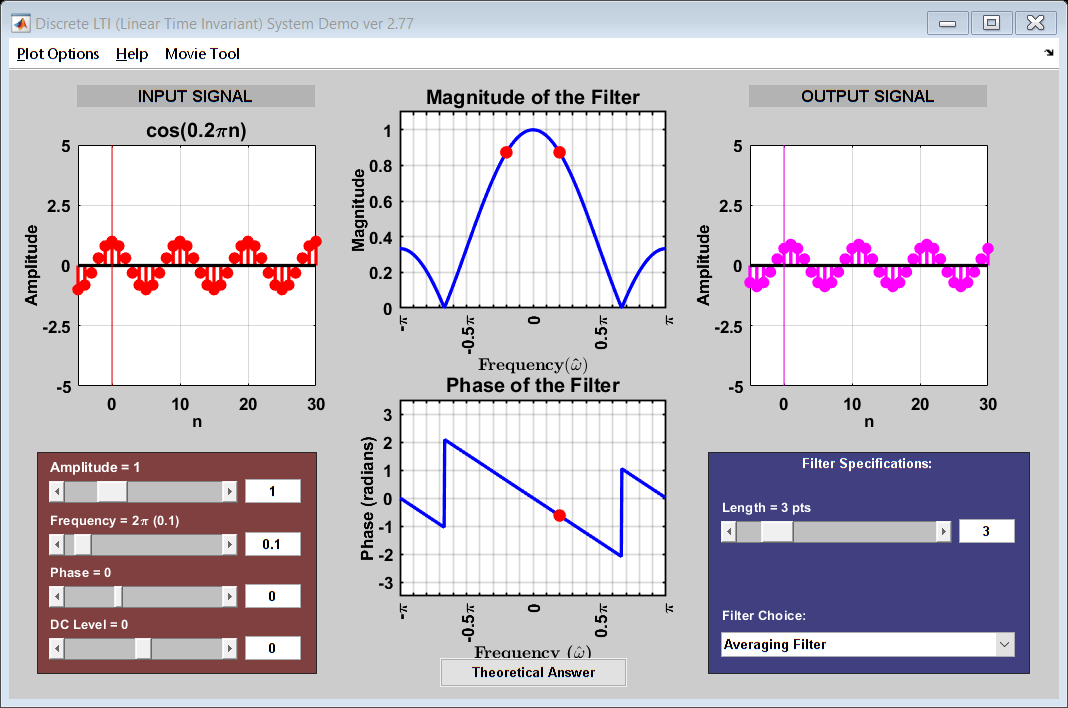

clear;
dltidemo;


% (c) Since the output signal is in the form: y[n] = 1.05 cos (0.1πn -
% 0.8π), it can be rewritten to be in the form: y[n] = 1.05 (0.1π (n - 8).
 
% (d) Due to the input signal's nd being 4 and the output signal's nd being
% 8, we can calculate the delay by: output - input = 8 - 4 = 4. This means
% the delay through the filter is 4.

% (e) The output signal became zero at length 20.

% (f) As a Nulling Filter, it is also able to negate frequencies that are
% intervals of 0.1π except 2π. This means it negates [..., -0.3π, -0.2π,
% -0.1π, 0.1π, 0.2π, 0.3π,...]

## 2.2 Cascading Two Systems

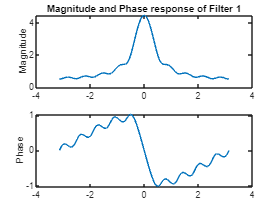

M = 9;
a = 0.8;
ww = -pi:(pi/100):pi;

% Filter 1
b1 = a.^(0:M);
HH1 = freqz(b1, 1, ww);

% Filter 2
b2 = [1, -a];
HH2 = freqz(b2, 1, ww);

% Filter 1 magnitude and phase
figure;
subplot(2, 1, 1);
plot(ww, abs(HH1));
ylabel('Magnitude');
title('Magnitude and Phase response of Filter 1');
subplot(2, 1, 2);
plot(ww, angle(HH1));
ylabel('Phase');

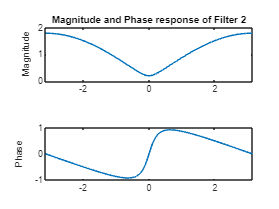


% Filter 2 magnitude and phase
figure;
subplot(2, 1, 1);
plot(ww, abs(HH2));
ylabel('Magnitude');
title('Magnitude and Phase response of Filter 2');
subplot(2, 1, 2);
plot(ww, angle(HH2));
ylabel('Phase');

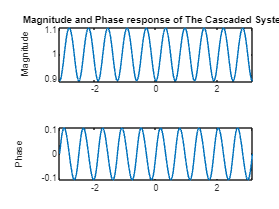


% Overall cascaded system
HH = HH1 .* HH2;

figure;
subplot(2, 1, 1);
plot(ww, abs(HH));
ylabel('Magnitude');
title('Magnitude and Phase response of The Cascaded System');
subplot(2, 1, 2);
plot(ww, angle(HH));
ylabel('Phase');


% (a) By observation of the generated graphs, Filter 1 is the lowpass 
% filter because its magnitude response shows a gradual decrease in 
% amplitude with increasing frequency.

% (b) The overall cascaded system combines both Filter 1 and Filter 2, so
% its frequency response is the product of both the individuals filters. 

% (c) The frequency responses of Filter 1 and Filter 2 are combined, which
% leads to a multiplication of their frequency responses in the frequency
% domain. This results in their overall magnitude response being the
% product of the magnitudes of the individual filters. The phase response
% are also added together which is apparent in the overall phase response
% of the overall cascaded system.

## 2.3 Deconvolution